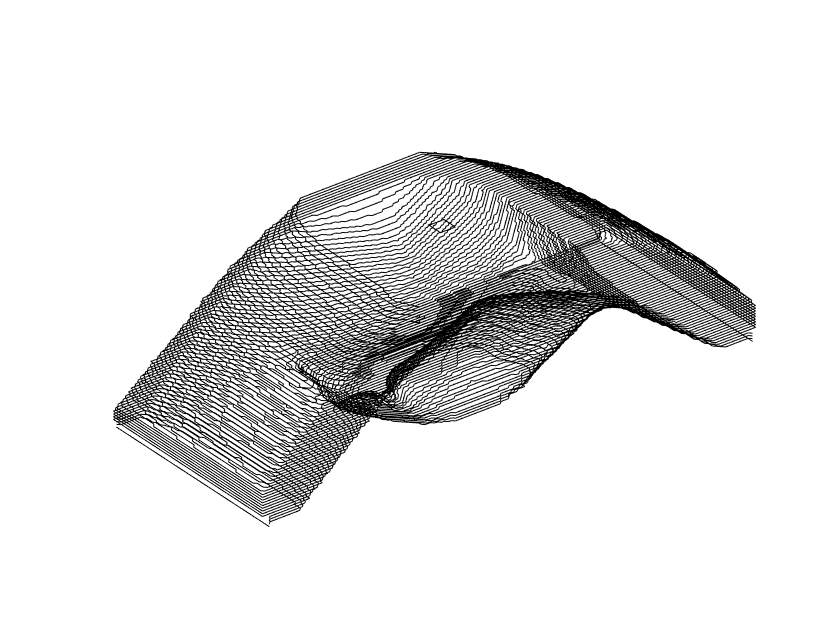

[Xq,Yq,Zq] = meshgrid(0:.25:nelx,0:.25:nely,0:.25:nelz);
Vq = interp3(X,Y,Z,Phi,Xq,Yq,Zq);
bPhi = double(Vq >= 0);
hold off;
for i = 1:(nelz*4+1)
xs = squeeze(Xq(:,:,i));
ys = squeeze(Yq(:,:,i));
zs = squeeze(Zq(:,:,i));
%surf(xs,ys,zs,squeeze(bPhi(:,:,i)));
contour3(i*squeeze(bPhi(:,:,i)),[i,i]);
colormap([0,0,0]); set(gcf,'color','w'); axis equal; axis off;
saveas(gcf,sprintf('z_%i.png', i));
colorbar off;
hold on;
end

colorbar off;